cell_num = 4

cell_num = 4

log_area = log(data(cell_num,:,2));
div_threshold = 0.2;
max_gr = 0.05;

Plot of log area for a mother cells growth

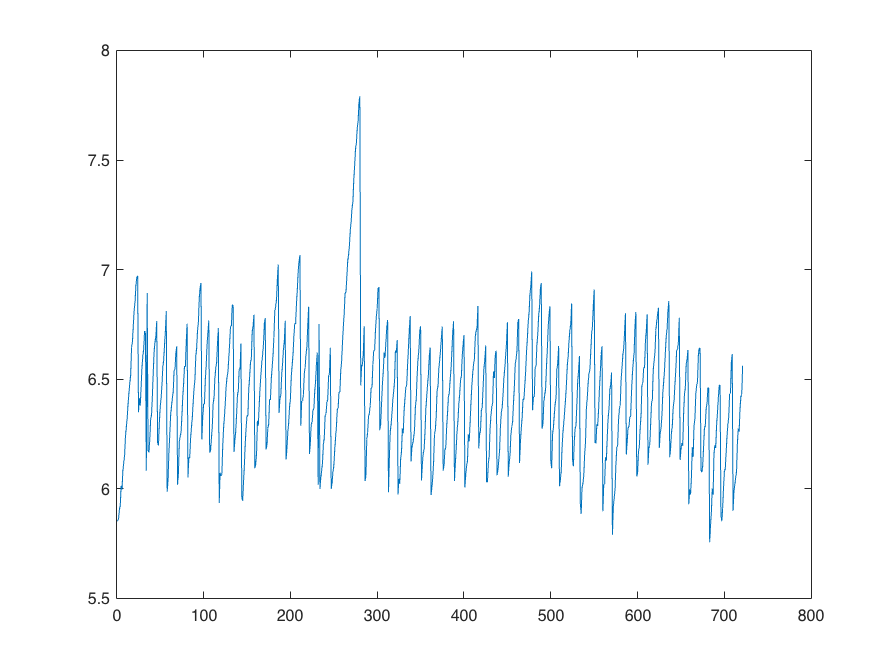

plot(log_area);

gr = diff(log_area);

Taking the derivative of the log area plot. Will set all values below the threshold of -0.4 to 0

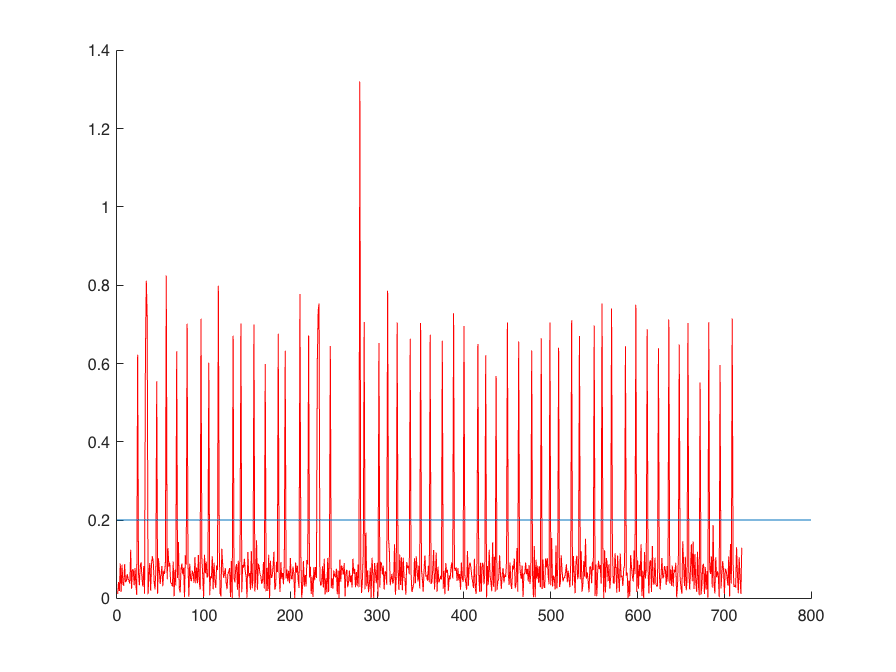

clf
hold on
plot(abs(gr),'Color','r')
line([0,800],[1,1]*div_threshold)
hold off

Setting all values below the threshold of -0.4 to 0

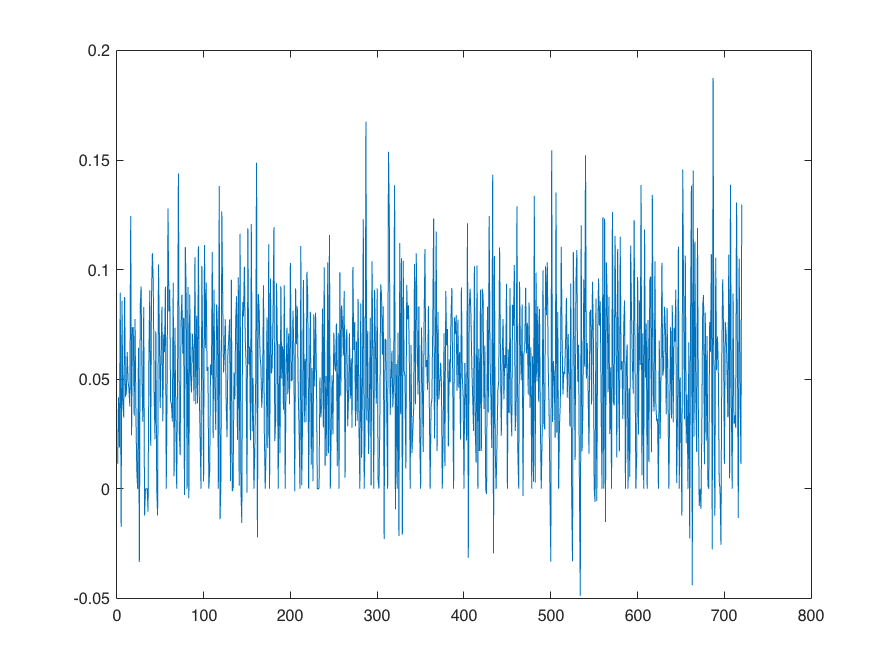

gr(abs(gr)>div_threshold)=0;
plot(gr)

Finding the cumulative sum of the above graph to find the lagtime graph

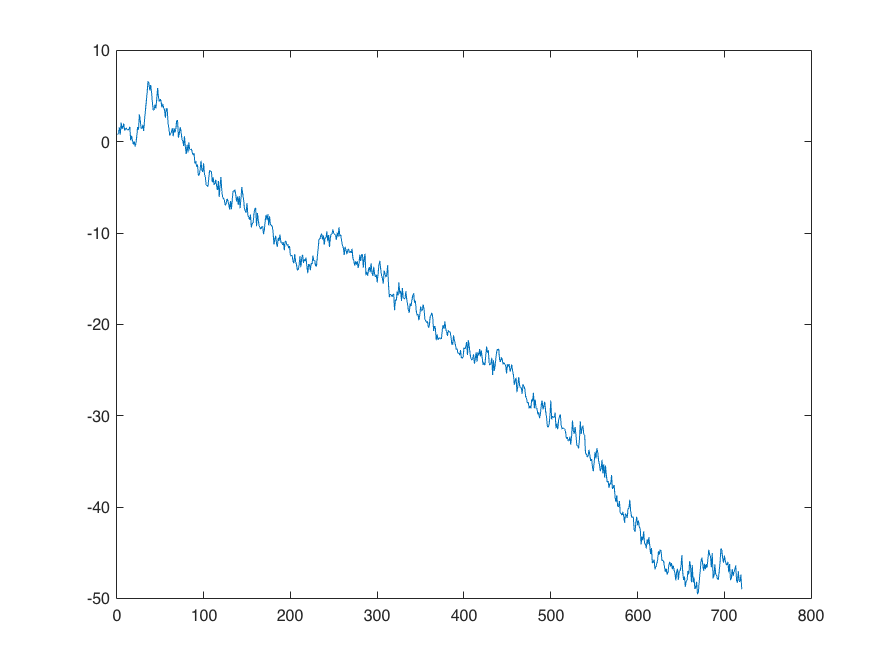

lagt = (1:720) - cumsum(gr)/max_gr;
clf
plot(lagt)

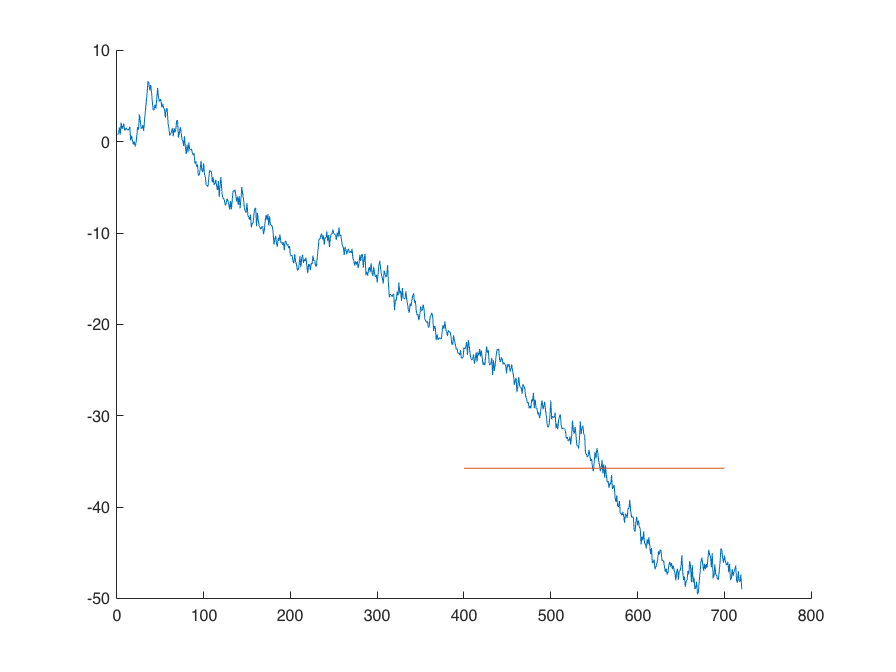

range_fit = 400:700;
lag_asym = polyfit(range_fit,lagt(1,range_fit),0);

lagt_in_range = lagt(1,range_fit);

clf
hold on
plot(lagt);
plot(range_fit,lag_asym*ones(1,length(range_fit)));
hold off

clf
cv = std(lagt_in_range-lag_asym)/mean(lagt_in_range-lag_asym)

cv = 1.0396e+15

The lagtime is the asymptote of the above graph, hence this cell has a lagtime of roughly 

Which is roughly 101 timepoints hence 202 minutes : 3h 22minutes at which point it reaches its exponential growth phase

% cell_num =1;
% range = 10:720;
% log_area = log(data(cell_num,:,2));
% [lagtime,lag_to_exp] = lagtime(0.05,log_area);
% clf
% hold on
% plot(lagt)
% hold off

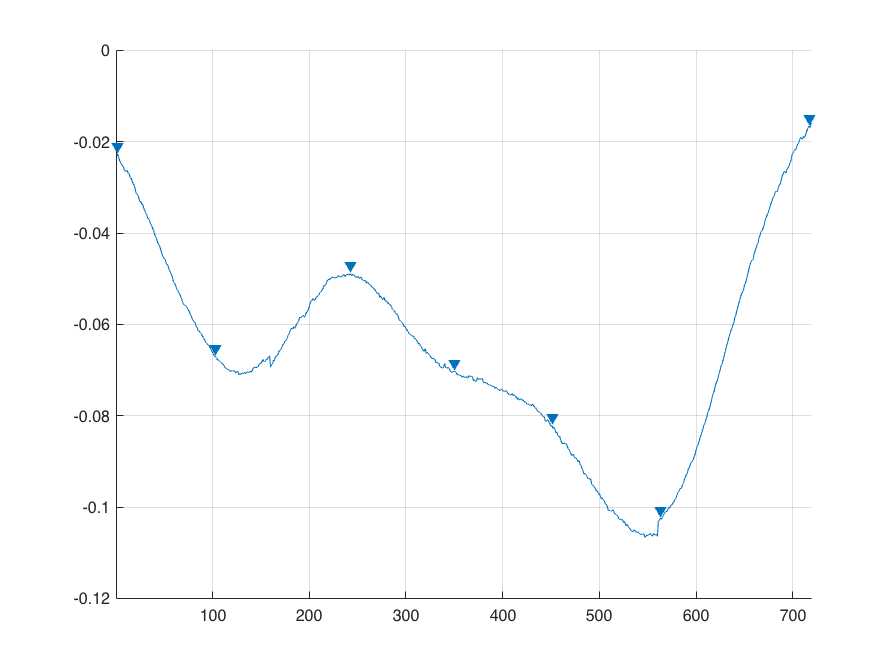

clf
smooth_lagt =  smoothdata(lagt,'gaussian');
hold on
%plot(smooth_lagt)
findpeaks(diff(smooth_lagt),"SortStr",'descend','MinPeakDistance',100)
[pks,locs] = findpeaks(diff(smooth_lagt),"SortStr",'descend','MinPeakDistance',100);
hold off

%plot(csum)
CV = [];
END_LAG = [];
YFP = [];
for c=1:178
    log_area = log(data(c,:,2));
    yfp = mean(data(c,300:700,36));
    [lagt] = lagtime(max_gr,log_area);
    END_LAG = [END_LAG,lagt(end)];
    YFP = [YFP, yfp];
end

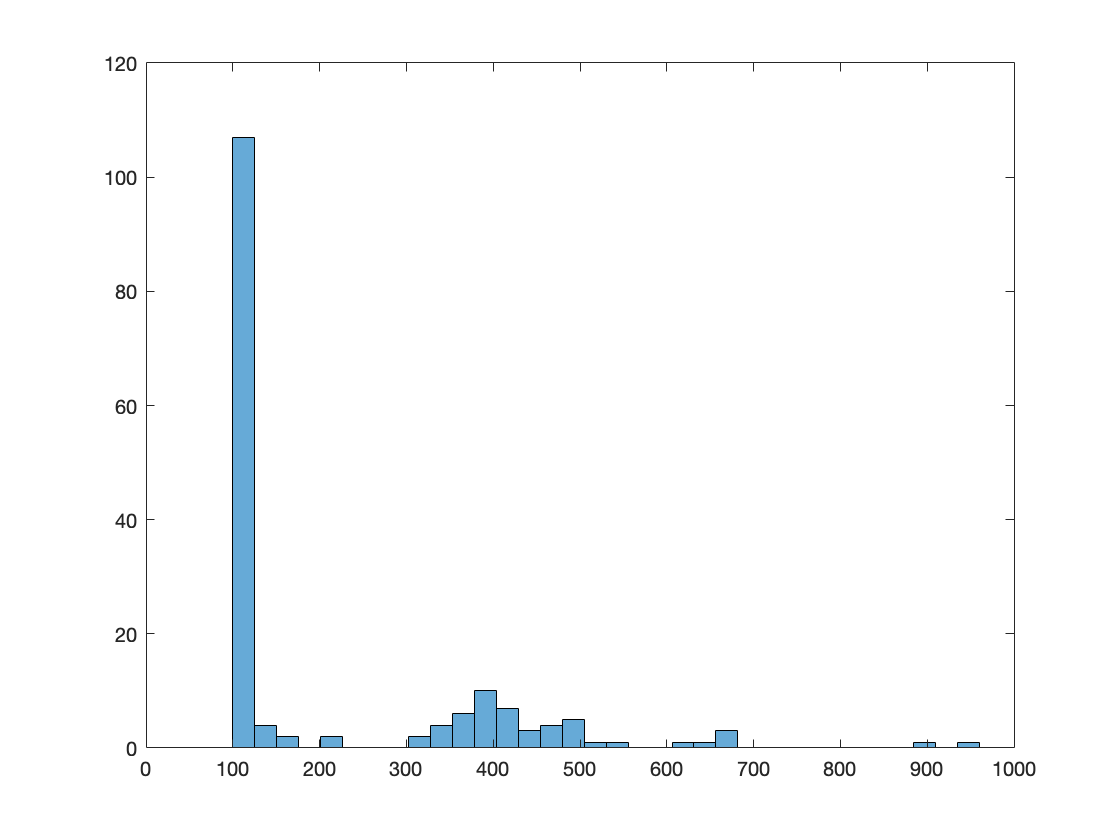

histogram(YFP,150)
xlim([0,1000])

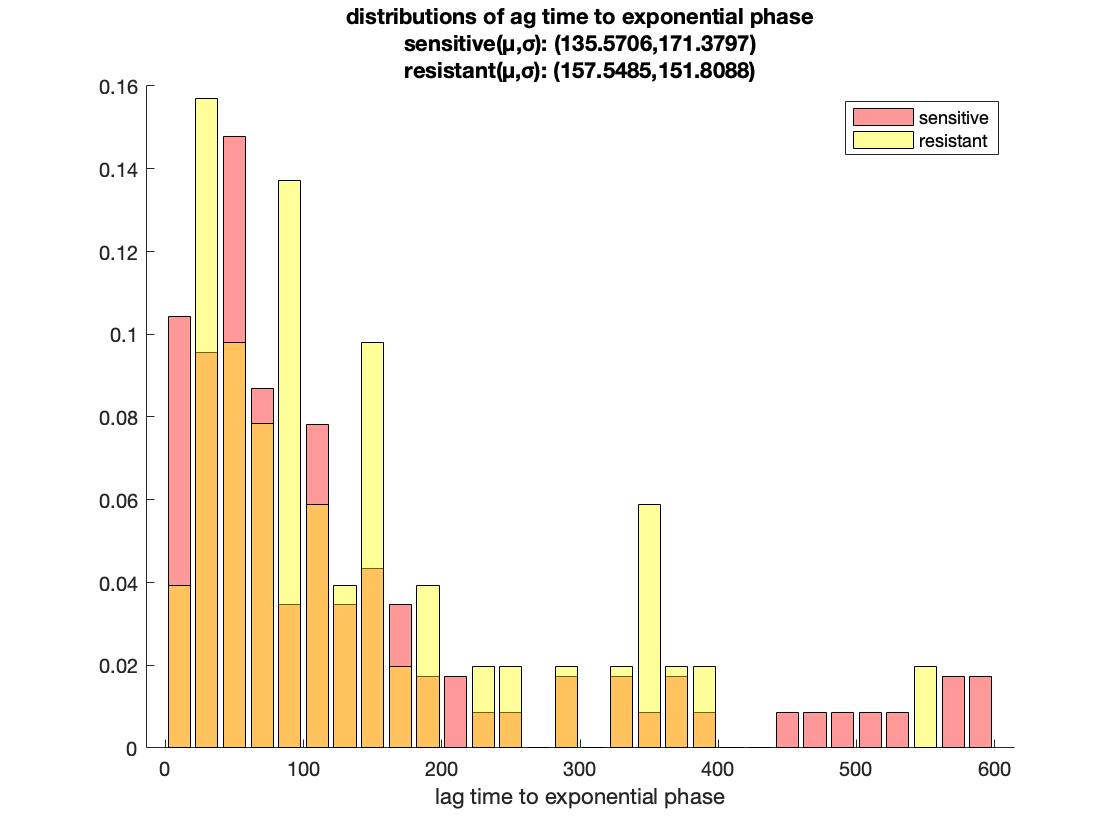


lag_res = END_LAG(YFP > 250);
m_lag_res = mean(lag_res);
s_lag_res = std(lag_res);

lag_sens = END_LAG(YFP <= 250);
m_lag_sens = mean(lag_sens);
s_lag_sens = std(lag_sens);

res = 20;
E = 0:res:600;
[sN,sedges] = histcounts(lag_sens,E,'Normalization','probability');
[rN,redges] = histcounts(lag_res,E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off

xlabel("lag time to exponential phase")
title(["distributions of ag time to exponential phase",...
    "sensitive(μ,σ): ("+num2str(m_lag_sens)+","+...
    num2str(s_lag_sens)+")", ...
    "resistant(μ,σ): ("+num2str(m_lag_res)+","+...
    num2str(s_lag_res)+")"])
legend(["sensitive","resistant"])